golden = imread('golden.jpg');
golden_gauss = imnoise(golden,"gaussian");
golden_salt = imnoise(golden,'salt & pepper');

b=2000;
[height,width,deep] = size(golden);
%noise = sqrt(-b*log((1-rand(h,w))));
noise = sqrt(-b*log((1-rand(height,width,deep))));
%noise=repmat(noise,1,1,3);
golden_rayle = uint8(double(golden)+noise);

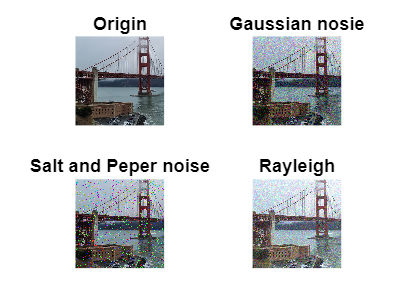

figure,
subplot(2,2,1);
imshow(golden),title("Origin")
subplot(2,2,2);
imshow(golden_gauss),title('Gaussian nosie')
subplot(2,2,3);
imshow(golden_salt),title('Salt and Peper noise')
subplot(2,2,4)
imshow(golden_rayle),title('Rayleigh')

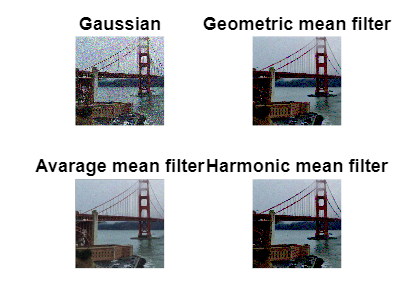

figure,
g = double(golden_gauss);
m = 5; n = 5;
subplot(2,2,1)
imshow(golden_gauss),title('Gaussian')

subplot(2,2,2)
f_geome = exp(imfilter(log(g),ones(m,n),'replicate')).^(1/(m*n));
imshow(uint8(f_geome)),title('Geometric mean filter')

subplot(2,2,3)
f_arith = imfilter(g,fspecial('average',[m n]));
imshow(uint8(f_arith)),title('Avarage mean filter');

subplot(2,2,4)
f_harmo = (m*n) ./ imfilter(1 ./ (g + eps), ones(m, n), 'replicate');
imshow(uint8(f_harmo)),title('Harmonic mean filter');

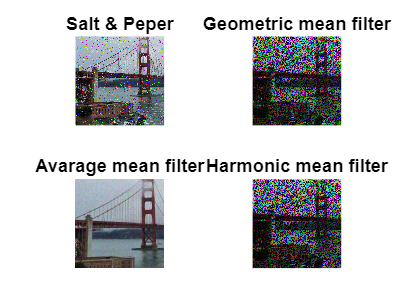

figure,
g1 = double(golden_salt);
m = 5; n = 5;
subplot(2,2,1)
imshow(golden_salt),title('Salt & Peper')

subplot(2,2,2)
f_geome = exp(imfilter(log(g1),ones(m,n),'replicate')).^(1/(m*n));
imshow(uint8(f_geome)),title('Geometric mean filter')

subplot(2,2,3)
f_arith = imfilter(g1,fspecial('average',[m n]));
imshow(uint8(f_arith)),title('Avarage mean filter');

subplot(2,2,4)
f_harmo = (m*n) ./ imfilter(1 ./ (g1 + eps), ones(m, n), 'replicate');
imshow(uint8(f_harmo)),title('Harmonic mean filter');

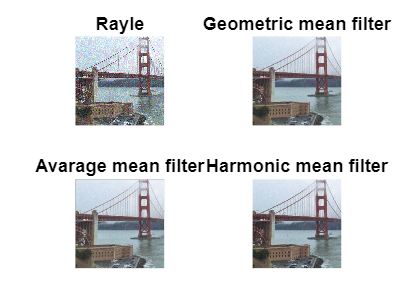

figure,
g2 = double(golden_rayle);
m = 5; n = 5;
subplot(2,2,1)
imshow(golden_rayle),title('Rayle')

subplot(2,2,2)
f_geome = exp(imfilter(log(g2),ones(m,n),'replicate')).^(1/(m*n));
imshow(uint8(f_geome)),title('Geometric mean filter')

subplot(2,2,3)
f_arith = imfilter(g2,fspecial('average',[m n]));
imshow(uint8(f_arith)),title('Avarage mean filter');

subplot(2,2,4)
f_harmo = (m*n) ./ imfilter(1 ./ (g2 + eps), ones(m, n), 'replicate');
imshow(uint8(f_harmo)),title('Harmonic mean filter');

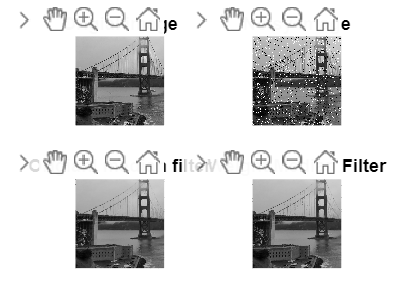

golden = rgb2gray(imread('golden.jpg'));

golden_noise=imnoise(golden,'salt & pepper',0.09);

W = ones(5);
W(3,3)=5;

figure,
subplot(2,2,1)
imshow(uint8(golden)),title('Origial image')
subplot(2,2,2)
imshow(uint8(golden_noise)),title('Noisy image')
subplot(2,2,3)
imshow(uint8(med_filter(golden_noise,5))),title('Origianl median filter')
subplot(2,2,4)
imshow(uint8(weightedmedianfilter(golden_noise,5,W))),title('Weight Median Filter')